# Question 2

figure;
hold on;
r = 1;
th = 0:pi/50:2*pi;
xunit = r * cos(th);
yunit = r * sin(th);
h = plot(xunit, yunit);

rectangle('Position',[-1 -1 2 2])
x0=10;
y0=10;
width=550;
height=520;

N = sqrt(1000);
x = linspace(-1, 1, N);
x = repmat(x, 100, 1);
x = x(:);
y = linspace(-1, 1, N);
y = repmat(y, 100, 1);
y = y';
y = y(:);
sz = 15;

c = zeros(1, length(x));
count = 0;

for i=1:length(x)
    x1 = x(i, 1);
    y1 = y(i, 1);
    h = sqrt((x1^2) + (y1^2));
    if h <= 1
        count = count + 1;
        c(1, i) = 1;
    else
        c(1, i) = 0;
    end
end

scatter(x,y,sz,c,'filled')
set(gcf,'position',[x0,y0,width,height])

total_points = length(x)

total_points = 3100

count

count = 2292


pi_estimation = 4 * (count / total_points)

pi_estimation = 2.9574

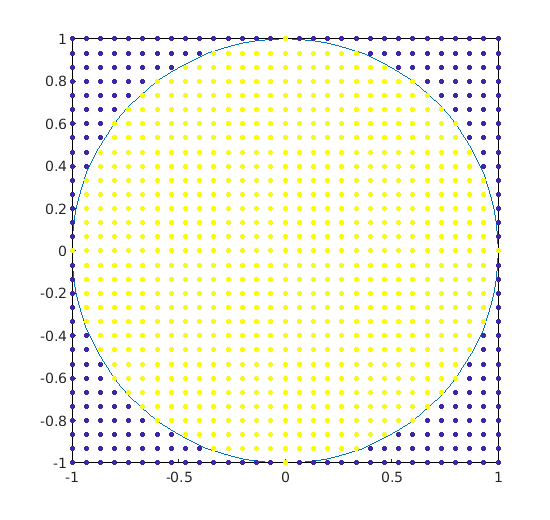

saveas(gcf,'100points.jpg')